# Intro to Problem Solving 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Problem solving is a versatile approach that spans multiple fields and disciplines. Whether it's designing a toy that brings joy to children, constructing roads and off-ramps to ease traffic congestion, developing medical devices that simplify heart stent installation, or innovating fully solar-powered commercial airplanes, these endeavors illustrate how problem solving can range from relatively simple to highly complex challenges. Generally speaking, solving problems is the primary driver behind innovation in the fields of science and engineering. In this script, we will explore engineering problem solving through the lens of systems thinking.

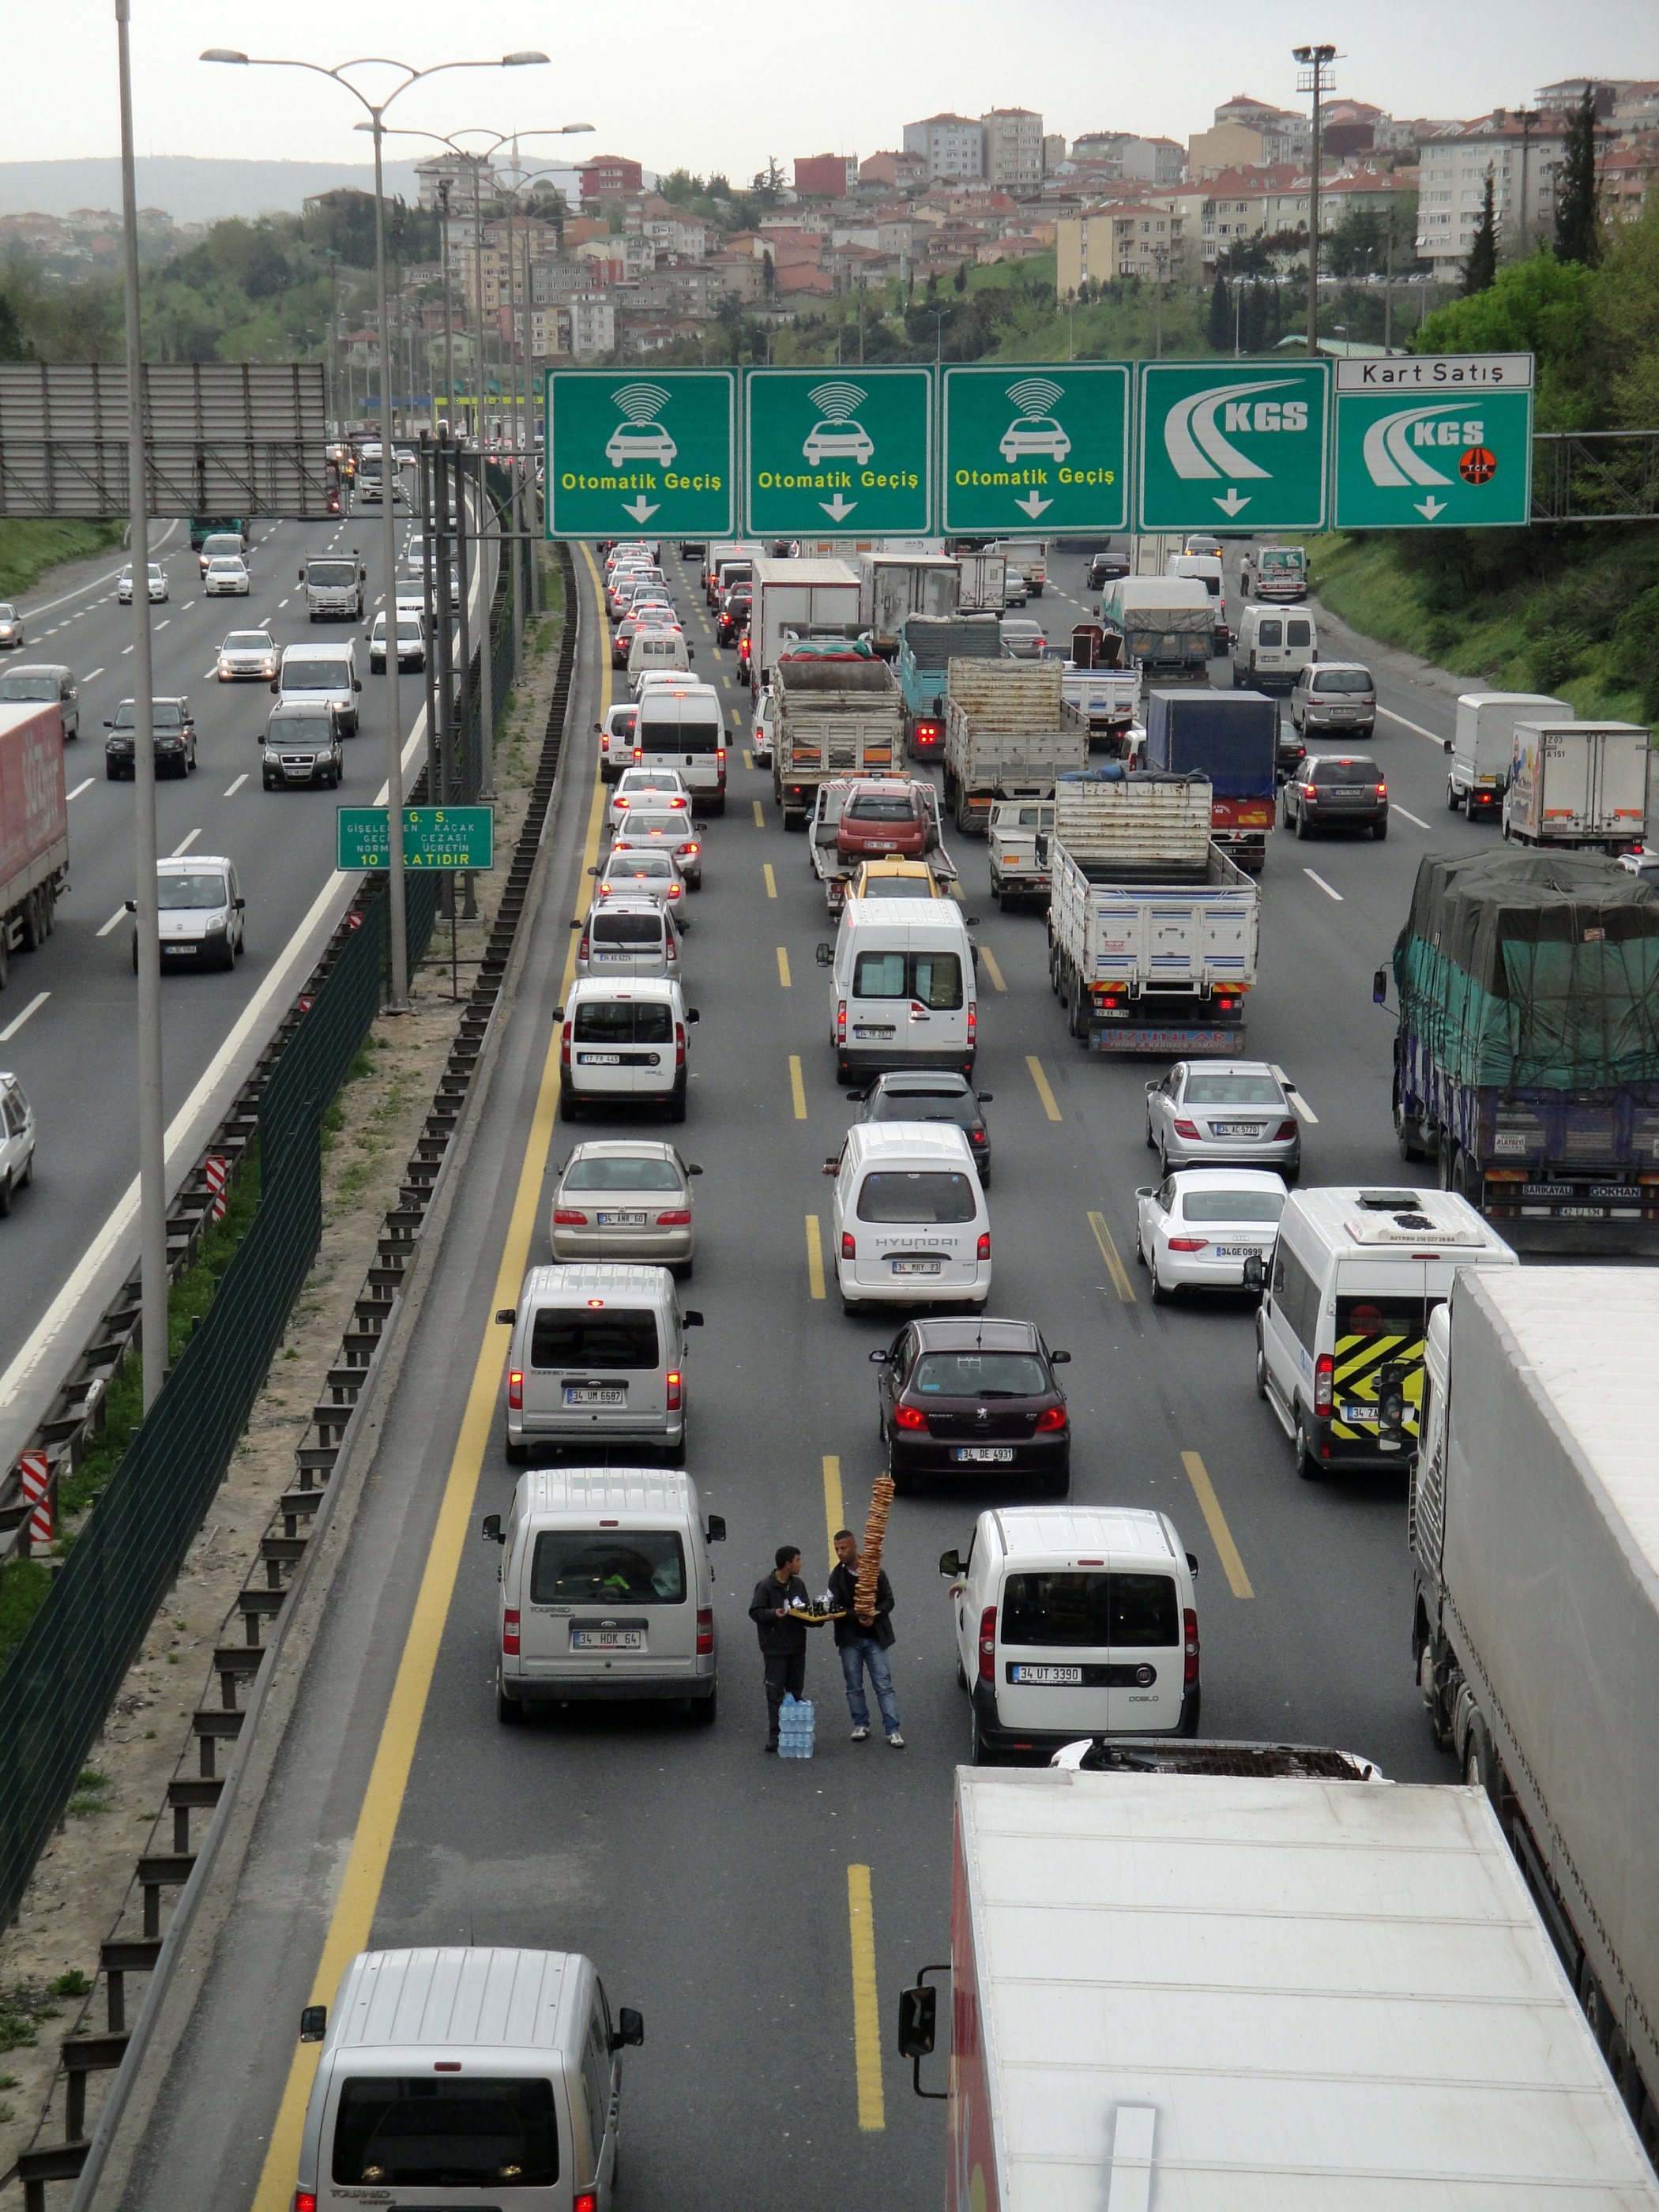

A photograph of Istanbul traffic by [Reise Reise](https://commons.wikimedia.org/wiki/File:Istanbul_Otoyol_2_Richtung_FSM_2.jpg), [CC BY-SA 3.0](https://creativecommons.org/licenses/by-sa/3.0/deed.en)

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) and [Simulink Onramp](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink), both are free 2 hour online tutorial that teaches the essentials of MATLAB and Simulink, respectively.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction to systems

We are surrounded by systems in our daily lives. Imagine your city as a system: it comprises houses, which contain rooms, and people living within them. Each is an individual yet interconnected system, forming a *system of systems*. These interconnections prompts questions about mutual impacts: How does a person affect a room? How do room changes influence a house? How do house changes affect the city? These questions apply in reverse as well. This approach is called systems thinking, a crucial aspect of systems engineering, which is essential for managing complex problems.

***"The whole is greater than the sum of its parts." - Aristotle (Philosopher)***

 **Exercise 1. **The ocean is one of the largest systems on the planet. Which of the following can affect the ocean **AND** are affected by the ocean? Please select all that apply and click the **Submit Answers** button below.  

exerciseSol1(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);
 

 **Reflect. **We have used systems thinking and applied it to cities and oceans so far. Let's scale back the idea of systems thinking to something easier to relate to. Think about needing to buy a car or needing to enroll for a class in your degree program. What kinds of questions might you ask to better frame your problem?

### Systems project: Delivery drone

Throughout this module, there will be a variety of different examples solving systems-based problems. Consider these examples as practice for the main project in this module, which involves exploring problem-solving related to package delivery using a quadcopter [1]. A quadcopter, or more commonly known as a drone, is also a system of systems. It is an intricate device that requires many systems to function properly and safely. 

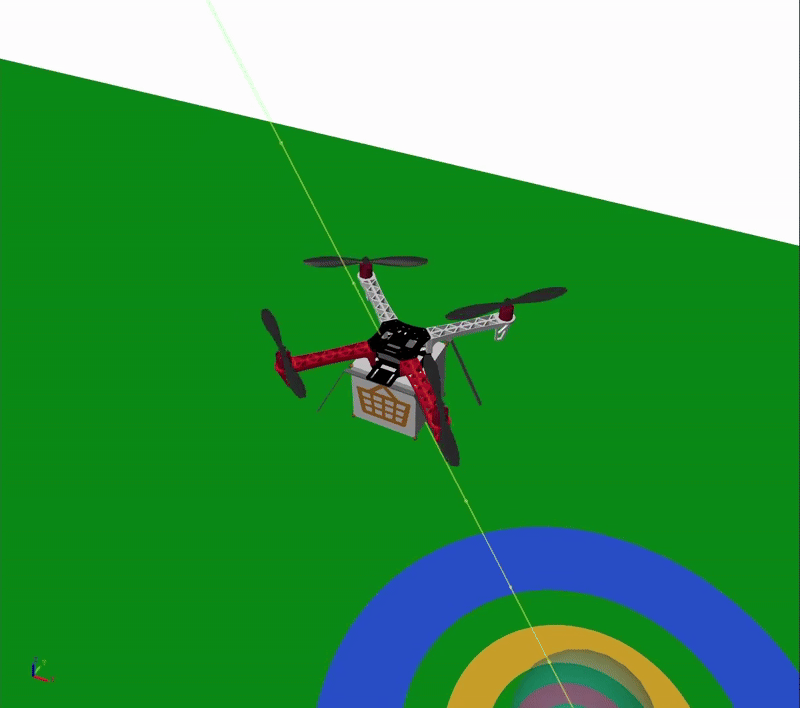

Visualization of a drone delivering a package and returning to its origin

It is important to understand the performance envelope (limitations) of the drone before trying to solve the problem of package delivery. In designing a drone for this particular task, consider some thoughts:

- How much weight can the drone carry?

- How far can the drone fly?

- What kind of environment will the drone operate in?

- What is the allowable size(s) for a drone to perform this kind of task?

- What does the drone have to interact with? (People, Buildings, Communication towers, Other aircraft, etc.)

interaction1("Select an answer...");

## Problem solving and systems engineering 

Systems engineering methodologies are essential for problem-solving, focusing on understanding problems and finding effective solutions. Technology has made this easier by enabling computers to create and solve mathematical models. Imagine the level of difference in computational power between a calculator and a supercomputer. These models, whether virtual or physical, are at best, only as accurate as the input data. Precision in solutions depends on the problem's requirements. Models are tools for gaining insights rather than just finding correct answers. Unlike a jigsaw puzzle where pieces fit predictably, solving complex system problems often involves finding acceptable rather than perfect solutions, due to unpredictable interactions.

***"All models are wrong, but some are useful." - George Box (Statistician)***

### **Bungee jumping example pt. 1**

** Demonstration**. Let's consider a virtual model that solves a [bungee jumping](https://en.wikipedia.org/wiki/Bungee_jumping) problem. The bungee jumper (mass) and cord (spring) can be expressed as a [mass-spring system](https://en.wikipedia.org/wiki/Harmonic_oscillator#Spring/mass_system) model, where the positive direction of movement ($x$) is upward. Note that the mass and the spring are both separate but connected systems. The bungee jumper has an initial height of 80 meters. Using the given information, find and plot the maximum depth attained by the bungee jumper before reaching the ground (0 meters).

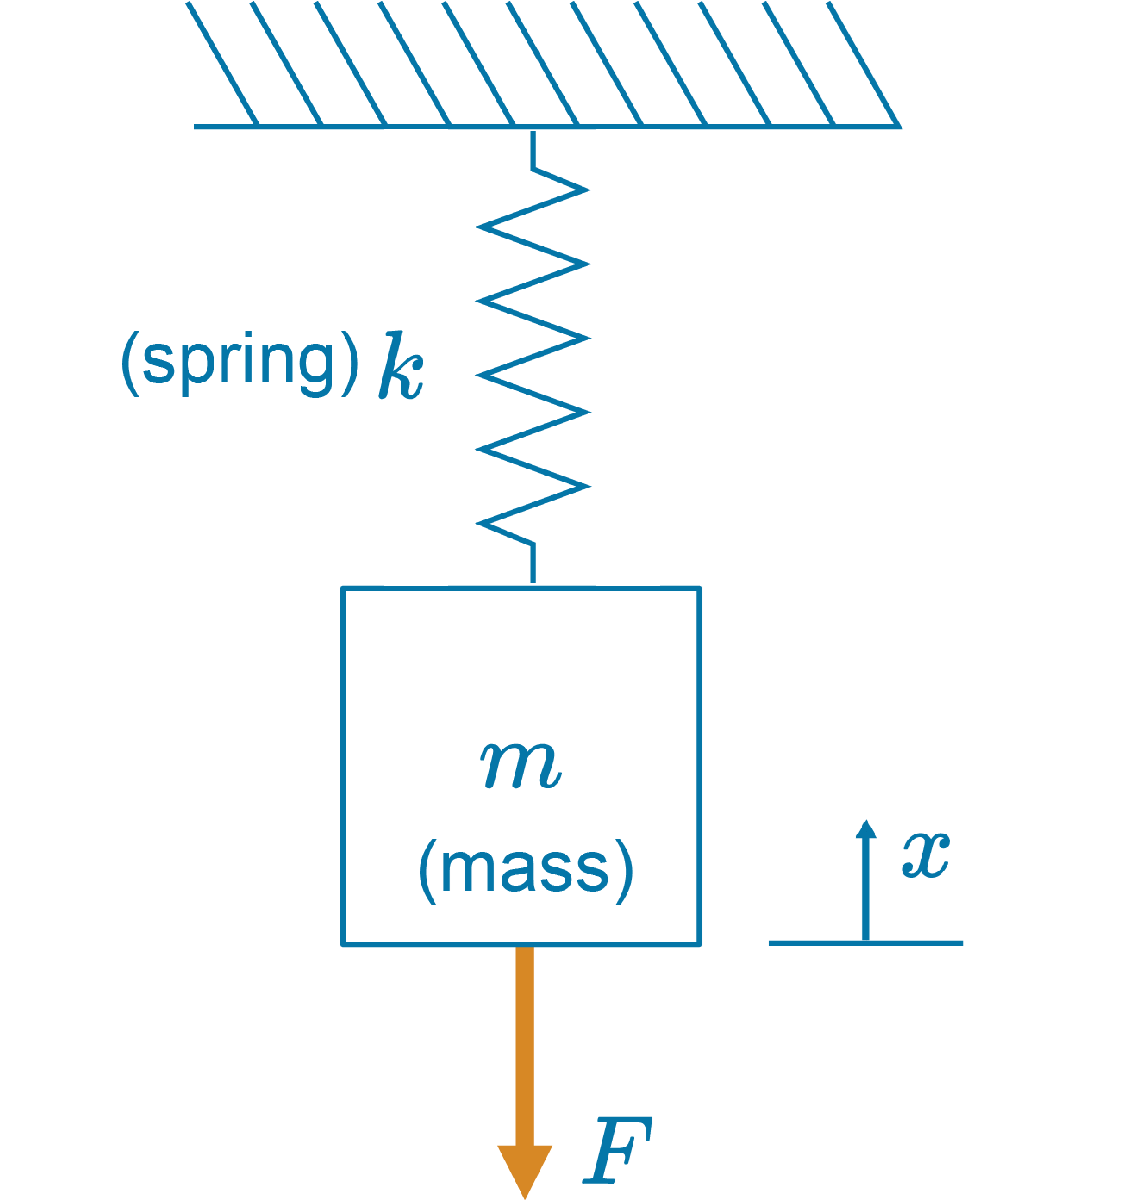

**Note**. From general physics, taking the double integral of acceleration ($\ddot x$) gives us position ($x$).

  **Try**. Explore the bungee jumping Simulink model. A mathematical model of the mass-spring system will be used to solve this problem. The solution in the model will look similar to the integral form listed above. Observe in the model that the spring force of the bungee cord is defined by a piecewise function for its unstretched vs stretched position. As cord position x changes with time, the elastic force exerted by the cord changes. After opening the model, simulate the model using the run icon  . Then, view the bungee jumper position over time using the check box below.

 

% Check if project is open. If not, add folders to path.
try
    % Open Simulink model for bungee jumping 
    open_system("Models/BungeeJumping.slx");
catch ME
    curloc = matlab.desktop.editor.getActiveFilename;
    rootdir = extractBefore(curloc,filesep+"Scripts");
    addpath(genpath(rootdir));
    open_system("Models/BungeeJumping.slx");
end

bungeeFlag = false;

if  bungeeFlag
    % Plot the bungee cord position
    if ~exist("out1","var") %#ok<UNRCH>
        warning("Please open and run the model prior to checking this box.")
        return
    end
    simData = out1.logsout{1}.Values;
    t1 = simData.Time;
    p1 = simData.Data;
    t2 = t1;
    p2 = zeros(size(t1,1),1);
    plot(t1,p1,'-',t2,p2,'--','LineWidth',2);
    grid;
    xlabel('Time (sec)'); ylabel('Position (m)');
    title('Bungee Jumper Position');
    legend("Bungee Position","Ground")
end

 **Reflect. **Is this a realistic representation of what would happen when someone bungee jumps?

 **Exercise 2. **Recall the discussion about solution precision in a model. What additional factors could make this mass-spring representation of a bungee jumper more accurate? Please select all that apply and click the **Submit Answers** button below.

exerciseSol2(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);
 

### **Bungee jumping example pt. 2**

** Demonstration**. Let's add in the additional factor to make the bungee jumper model solution more accurate. Since air resistance is a drag force, it can be modeled as a damper in the system. Therefore, we will characterize air resistance with a damper, another separate but connected system, transforming our mass-spring system into a [mass-spring-damper system](https://en.wikipedia.org/wiki/Mass-spring-damper_model). Using the given information, find and plot the maximum depth attained by the bungee jumper before reaching the ground (0 meters).

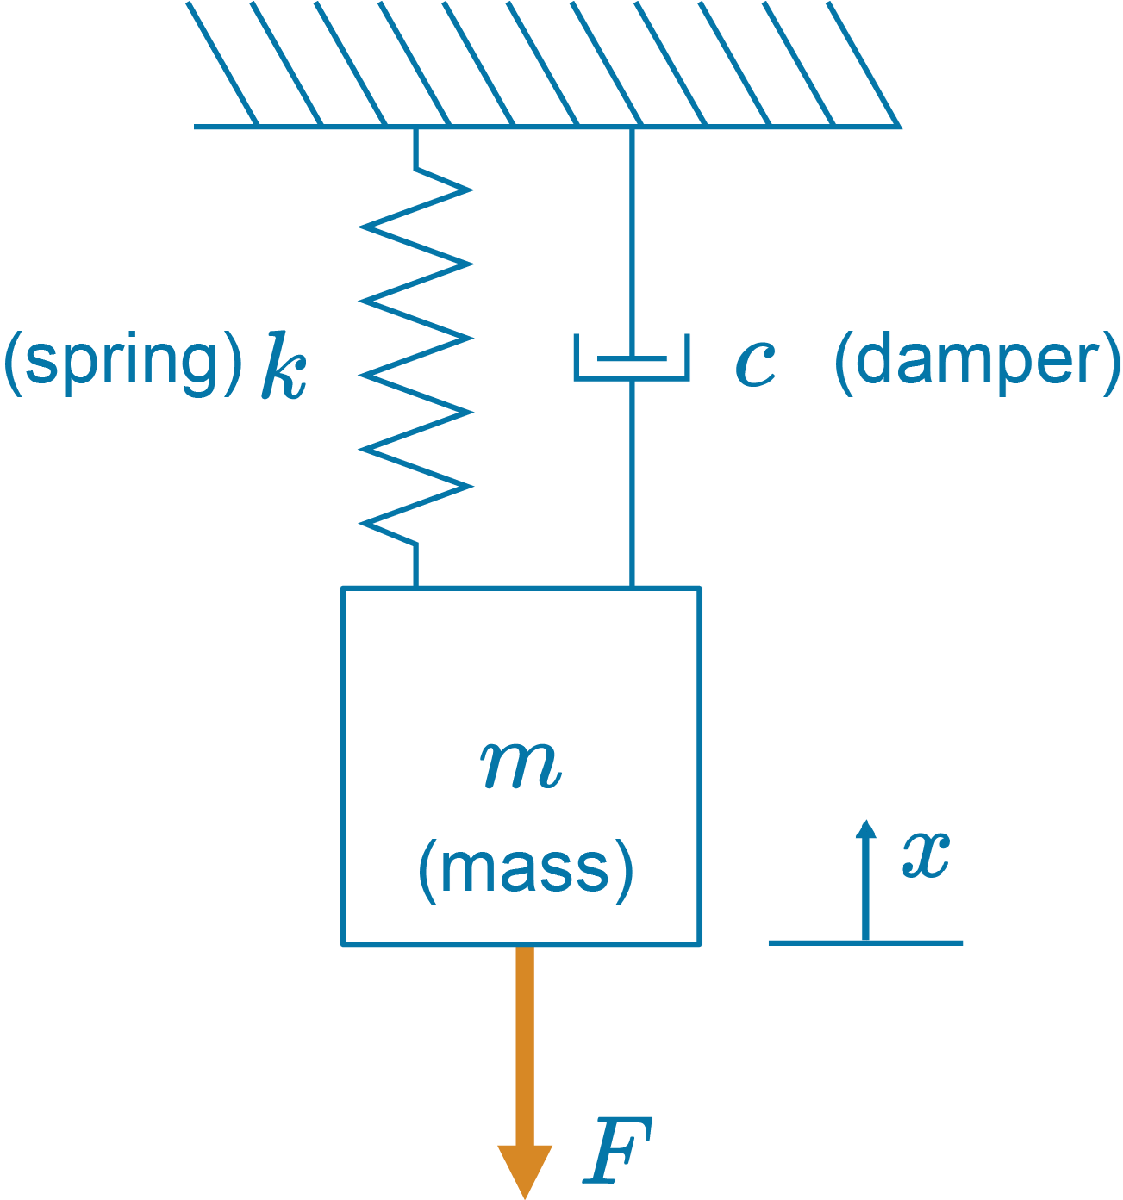

  **Try**. View the bungee jumper position over time using the check box below, this time with the addition of the drag force. Compare the two signals to see the impact of the additional force that was added to the system. Finally, open the bungee jumping simulink model with drag to review, as it will be needed later in this script. Observe in the model that the drag force acting on the bungee jumper is dependent on surface area of the jumper, coefficient of drag for air, and air density. The solution in the model will look similar to the integral form listed in the table above.  

bungeeDragFlag = false;

if  bungeeDragFlag
    % Run bungee cord model with drag
    out2 = sim("Models/BungeeJumpingDrag.slx","StopTime","50"); %#ok<UNRCH>

    % Plot the bungee cord position with Drag
    simData1 = out1.logsout{1}.Values; 
    simData2 = out2.logsout{1}.Values;
    t1 = simData1.Time;
    p1 = simData1.Data;
    t2 = simData2.Time;
    p2 = simData2.Data;
    t3 = t1;
    p3 = zeros(size(t1,1),1);
    plot(t1,p1,':',t2,p2,'-',t3,p3,'--','LineWidth',2);
    grid;
    xlabel('Time (sec)'); ylabel('Position (m)');
    title('Bungee Jumper Position Comparison');
    legend("Bungee Position Original","Bungee Position with Drag","Ground")
end

 

% Open simulink model for bungee jumping with drag 
open_system("Models/BungeeJumpingDrag.slx")

### Bungee jumping example parameter sweep

Based on the table of equations above, drag force is dependent on the surface area of the jumper. The mass of the jumper will also impact how far the cord will stretch. We can compare different combinations of mass and area using the [Simulink Data Inspector](https://www.mathworks.com/help/simulink/slref/simulationdatainspector.html) (SDI) to better understand how the system responds. Let's explore the interconnections of these systems further using the current model.

  **Try**. **Update the MATLAB Workspace variables (**$m\;\textrm{and}\;A$**) based on the table below**. Open the SDI using the code snippet below by pasting it into the MATLAB command window. Ignore the getting started screen. For each scenario, change the mass and area values in the workspace and then **rerun the bungee jumping model with drag**. Notice that new signals will appear in the SDI "Inspect" window. You can rename the signals to coincide with the scenario. **Finally, once you have all 3 signals available in SDI, select the "Compare" button to observe how the bungee jumper position changes as mass and area are varied. **What do you observe from the results?

 **Reflect**. The mass-spring system is a common way to express and understand complex dynamic behavior in real-world applications. Just as a bungee jumper (mass) is attached to a cord (spring), a package (mass) is attached to a drone's clamp (spring). In some cases, you have a damper, that generates resistance on the system. Apply these same ideas about solution fidelity from Exercise 2 about the bungee jumping problem to a drone. To increase the solution accuracy of the drone delivery problem, one might consider actual vs. ideal engine performance, gravity, and weather conditions, etc. What are some other factors?

## Modeling methodologies for systems

Previously, we discussed using virtual or physical models to represent systems. Consider more complex problems, like modeling [airplane landing gear](https://www.mathworks.com/help/sm/ug/airplane-wing-landing-gear.html), which is part of a larger, intricate system. Model-based design (MBD) offers a structured approach to solving complex problems. Developing a virtual model first provides significant advantages, such as organizing data, streamlining tests, exploring unknowns, and accelerating solution finding. A virtual model approach can reduce project costs; for instance, imagine the costs associated with crash testing a car to determine its safety and structural strength. A virtual model might not stop you from having to perform a destructive test, but it may reduce the number of times the destructive test must be performed in order to meet a particular safety standard. Similarly, MBD was used to organize and explore the complex system of the drone from above. You can view and explore the model using the following button:

 **Warning. **If you are using MATLAB Online right now, the following button will open a **new instance** of MATLAB Online for the delivery drone model, and therefore exit out of this script. To return to this script, use/copy/save this link: [**Intro To Problem Solving**](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Engineering-Problem-Solving&project=EngineeringProblemSolving.prj&file=Scripts/IntroToProblemSolving.mlx)

 
web('https://matlab.mathworks.com/open/github/v1?repo=mathworks/Quadcopter-Drone-Model-Simscape&project=Quadcopter_Drone.prj');

 **Pro-tip. **Once the quadcopter model window is open, click on the maximize button in the top right corner to expand the model window full screen. Then, click on the canvas area and press the space button. This will resize the model for easier viewing.

Complexity varies by application and variables. While models simplify system design, understanding interconnections is crucial. Let's consider the delivery drone. Designing a single DC motor for a propeller is complex, but synchronizing four DC motors and propellers introduces further challenges with competing constraints, such as weight limitations and power management. Model-based systems engineering (MBSE) helps manage these complexities by using models instead of documents for information exchange. MBSE extends Model-Based Design (MBD) by aligning requirements and interactions among components to ensure product functionality. A key aspect of implementing MBSE is the V-model, which implements the *product development life cycle* (introduction to decommission) as a digital thread. The following V-model is not necessarily a standardized version and may vary depending on the industry. The purpose of this version is to understand that requirements are important to address and track throughout the life cycle of the product:

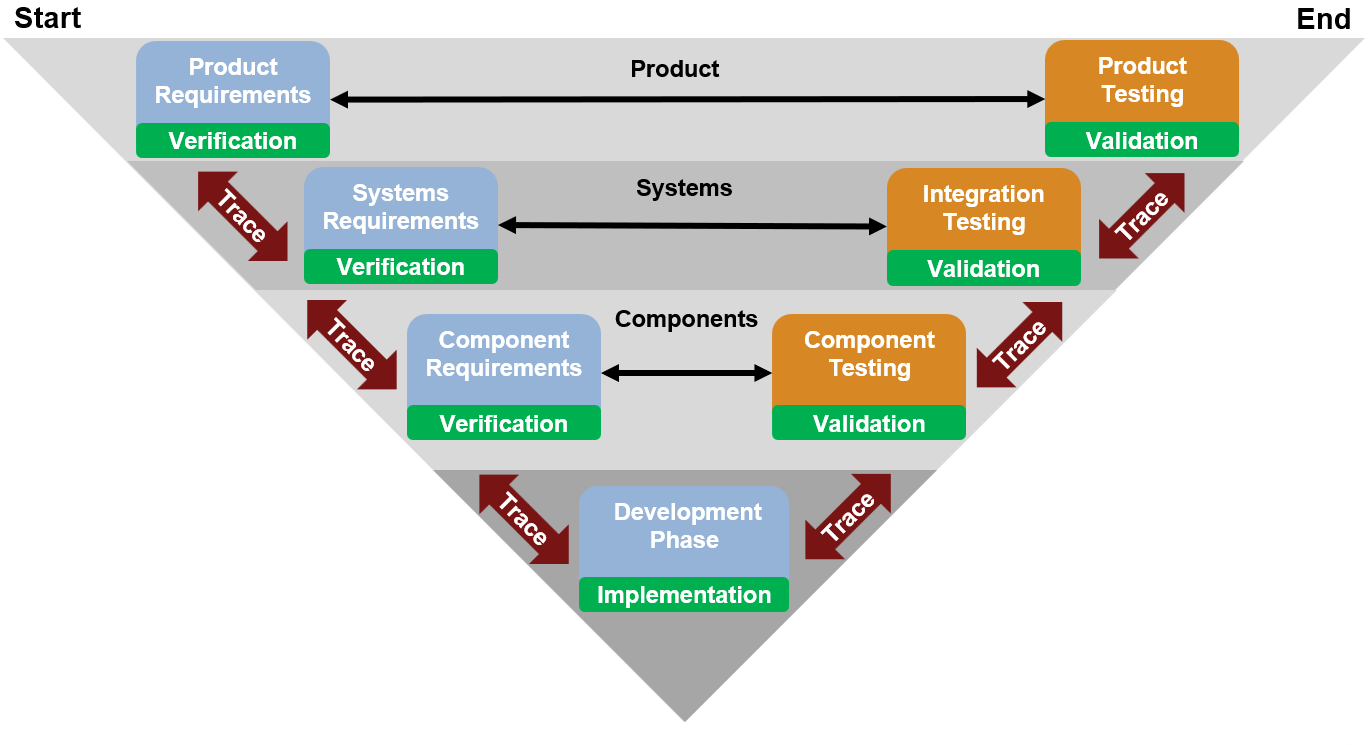

The V-model process moves from the top left of the V to the top right of the V. The left side focuses on the requirements of the system, its subsystems, and its components, having requirement traceability through all levels. The goal here is to verify your system meets the specifications for expected operation and performance. The bottom of the V is where you have sufficient definition and specification of your system to start developing solutions. The right side focuses on the build up/integration and testing of your system, having traceability through all levels. The goal is to validate your system meets the requirements defined by the customer needs.

MBSE paves the way for more efficient problem solving by:

- Reusing models for other projects or enhancements

- Navigating risk easier when a change in requirements presents itself during development (system flexibility)

- Improving collaboration among team members

- Providing early detection of errors and challenges

- Enhancing traceability for requirements from design to testing

  **Try**. Familiarize yourself with the quadcopter model by exploring all of its parts ([subsystems](https://www.mathworks.com/help/releases/R2024b/simulink/slref/subsystem.html)) using the model browser. Think about the V-model. What is the system or systems? What are the subsystems? What are the components?

 
web('https://matlab.mathworks.com/open/github/v1?repo=mathworks/Quadcopter-Drone-Model-Simscape&project=Quadcopter_Drone.prj');

  **Pro-tip**. To see the model browser (far left pane in the model window), run the following commands in the MATLAB Online Command Window once the quadcopter model is open.

As we progress through this module, we will be utilizing the V-model to work through the various parts of developing a quadcopter for package delivery. The main takeaway should not be on the development of the quadcopter, but on the simplification of the development for a quadcopter through a structured process.

### Build your own system

As models get larger in size, it becomes more difficult to build with only mathematical models. Previously, we worked on a mass-spring-damper as purely a mathematical model. Imagine the difficulty working with multiple mass-spring-dampers. Instead of a mathematical model, let's try a physical model this time. A physical model is represented by real components of a system rather than the components' mathematical representation. Within those components are the differential equations that define their operation. Before we move to the complexities of building a drone, let's start with something more simple to help build intuition. 

** Application. **Construct a mass-spring-damper physical system of the bungee jumping problem and compare the results to the previous example. Drag and drop the components from the model "**Parts List**" into the proper areas on the canvas. There is no need to change the parameters in the blocks as they have already been pre-set. **Run** the model once you have constructed it, and then use the check box below to compare the data.

 **Pro-tip. **To move a set of blocks all at once, click and drag the cursor across the canvas to select the blocks.

 

% Open simulink model for physical mass spring damper 
open_system("Models/BuildYourOwnMSD.slx")

msdFlag = false;

if  msdFlag
    if ~exist("out3","var") %#ok<UNRCH>
        warning("Please run your constructed mass-spring-damper model prior to checking this box.")
        return
    end

    % Plot the mathematical model vs the physical model
    simData2 = out2.logsout{1}.Values;
    simData3 = out3.logsout{1}.Values; 
    t2 = simData2.Time;
    p2 = simData2.Data;
    t3 = simData3.Time;
    p3 = simData3.Data;
    t4 = t2;
    p4 = zeros(size(t2,1),1);
    plot(t2,p2,':',t3,p3,'-',t4,p4,'--','LineWidth',2);
    grid;
    xlabel('Time (sec)'); ylabel('Position (m)');
    title('Bungee Jumper Position Model Comparison');
    legend("Mathematical Model", "Physical Model","Ground")
end

**Note**. Typically, when using the exact same parameters, the results of a mathematical model and physical model should match up perfectly. In this case, they do not. Why? Two reasons. First, the spring force is defined by a piecewise function not accounted for in the physical model. Second, the drag force is dependent on velocity, which isn't known because it must be implicitly solved for. Therefore, a constant max value for velocity (acquired from the mathematical model) was used to calculate the damping coefficient. For these reasons, the results will not match.

Upon completion of the previous activities, let's clean up our working environment:

 

% Check if project is open. If not, remove folders to path.
if isempty(matlab.project.rootProject)
    curloc = matlab.desktop.editor.getActiveFilename;
    rootdir = extractBefore(curloc,filesep+"Scripts");
    rmpath(genpath(rootdir));
else
    ...
end

## Customer needs

***"If you fail to plan, you plan to fail." - Benjamin Franklin (Scientist)***

We've discussed problem-solving complexities and methods to streamline the process. Project planning is crucial for successful product or service development. In traditional engineering, two major milestones assess project maturity: Preliminary Design Review (PDR) and Critical Design Review (CDR). PDR ensures the design meets requirements and objectives, while CDR confirms the design is complete and production-ready. These occur before the development phase. While it is exciting to innovate solutions to problems, it must be done within the context of what the *customer actually needs/wants*. System requirements are typically based on the customer's high-level requirements, which set the boundaries for problem-solving, with some leeway. Recall the V-model; you start with customer-driven product requirements and end with testing that aligns with these requirements. Broadly speaking, a holistic view of problem solving philosophy reveals that solving problems often stems from properly identifying a customer's need.

 **Exercise 3. **Before an engineering team begins implementing solutions, what events should happen first? Please select all that apply and click the **Submit Answers** button below.

exerciseSol3(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);
 

## Next Steps

This script covered a high level introduction to solving problems using systems thinking/engineering. In the next section, we will delve into defining system requirements to help establish constraints and facilitate problem solving.

## Further Exploration

- [MathWorks Problem Solving Projects/Challenges in Simulink](https://github.com/mathworks/MATLAB-Simulink-Challenge-Project-Hub)

- [Simscape Onramp](https://matlabacademy.mathworks.com/details/simscape-onramp/simscape)

- [Control Design Onramp with Simulink](https://matlabacademy.mathworks.com/details/control-design-onramp-with-simulink/controls)

- [Multibody Simulation Onramp](https://matlabacademy.mathworks.com/details/multibody-simulation-onramp/ormb)

## Glossary

**System** -  A group of interrelated parts that work together to achieve a goal or purpose. (↑ Return to Text)

**Systems Thinking** - A way of thinking about how parts of a system interact and influence each other. (↑ Return to Text)

**Systems Engineering** - An interdisciplinary approach that uses scientific and engineering principles to design, develop, and manage systems. (↑ Return to Text)

**Model** - A simplified description, especially a mathematical one, of a system or process to assist calculations and predictions. (↑ Return to Text)

**Model-based design** - A visual and mathematical method for designing complex systems that uses software models instead of direct code. (↑ Return to Text)

**Model-based systems engineering** - The formalized application of modeling to support system requirements, design, analysis, verification and validation activities beginning in the conceptual design phase and continuing throughout development and later life cycle phases. (↑ Return to Text)

**Requirement** - A documented need or condition that a particular product, service, or system must satisfy. (↑ Return to Text)

**V-model** - A graphical representation of the systems development lifecycle. (↑ Return to Text)

**Digital Thread** - A data-driven model of a product's lifecycle that connects all stages of its development, from design to disposal. (↑ Return to Text)

**Traceability** - The ability to track and document relationships between different elements of a system throughout its development lifecycle. (↑ Return to Text)

## References

[1] Miller, S. (2025, January 4). *Quadcopter Drone Model in Simscape*. Www.Mathworks.com. Retrieved June 23, 2025, from [https://www.mathworks.com/matlabcentral/fileexchange/63580-quadcopter-drone-model-in-simscape](https://www.mathworks.com/matlabcentral/fileexchange/63580-quadcopter-drone-model-in-simscape) (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function exerciseSol1(opts)
    % Provides solution for Exercise 1
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select all that apply!")
    elseif [opts.A opts.B opts.C opts.D] %#ok<BDSCA>
        disp("Correct! These are all examples of systems that can affect and/or be affected by the ocean.")
    elseif opts.A && ~any([opts.B opts.C opts.D])
        warning("Waste from whales contributes to the growth of phytoplankton in the ocean," + newline + "creating food sources for other marine life. Changes in ocean temperature can cause" + newline + "whales to migrate from their normal grounds. This is not the only correct answer.")
    elseif opts.B && ~any([opts.A opts.C opts.D])
        warning("Pollution in the ocean can harm marine life." + newline + "Ocean waves can dilute or disperse pollution, spreading" + newline + "the waste to various areas. This is not the only correct answer.")
    elseif opts.C && ~any([opts.A opts.B opts.D])
        warning("Coral Reefs act as a natural barrier to wave" + newline + "erosion, affecting how waves disperse marine organisms." + newline + "As the ocean heats up due to various factors, the change" + newline + "in temperature can kill coral reefs. This is not the" + newline + "only correct answer.")
    elseif opts.D && ~any([opts.A opts.B opts.C])
        warning("While not physically part of the ocean, cruise ships" + newline + "interact with the ocean. The ocean can affect ships with its waves," + newline + "creating an uncomfortable journey for passengers. Ships, as they pass" + newline + "through the ocean, can disturb ecosystems and wildlife. This is not" + newline + "the only correct answer.")
    else % Any other combination
        warning("Almost! You have not selected all the systems that can affect and/or be affected by the ocean.")
    end
end

function interaction1(choices)
    % Provides feedback for learning interaction
    arguments
        choices (1,1) string {mustBeMember(choices,["Select an answer..." "people." "questions." "answer." "genAI chatbot."])}
    end

    if choices == "Select an answer..."
    else
        if choices == "people."
            warning("Very close! While it is important to speak to the right people, there is a step before this that makes speaking to the right people more effective.");
        elseif choices == "questions."
            disp("Correct! Learning to ask the right questions will provide you with the best insight for understand the layers of solving a problem.");
        elseif choices == "answer."
            warning("Not quite. Sometimes knowing the answer can be helpful in working a problem backwards. This usually proves to be more difficult than working forward.");
        elseif choices == "genAI chatbot."
            warning("While genAI chatbots are useful in compiling information for a given prompt, it is still required that you provide some form of knowledge in your prompt to gain a better answer.");
        end
    end
end

function exerciseSol2(opts)
    % Provides solution for Exercise 2
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select all that apply!")
    elseif opts.A && ~any([opts.B opts.C opts.D])
        warning("The cord material is directly related to the value of the spring constant, and is already accounted for in the governing equation. Please try again.")
        open_system("Models/BungeeJumping.slx")
        hilite_system('BungeeJumping/Gravitational Force','none');
        hilite_system('BungeeJumping/1//mass','none');
        hilite_system('BungeeJumping/Spring Constant');
    elseif opts.B && ~any([opts.A opts.C opts.D])
        disp("Correct! Air drag or air resistance is an additional factor that could be added to increase model precision.")
    elseif opts.C && ~any([opts.A opts.B opts.D])
        warning("The mass of the jumper has already been accounted for in the governing equation. Please try again.")
        open_system("Models/BungeeJumping.slx")
        hilite_system('BungeeJumping/Spring Constant','none');
        hilite_system('BungeeJumping/Gravitational Force');
        hilite_system('BungeeJumping/1//mass');
    elseif opts.D && ~any([opts.A opts.B opts.C])
        warning("Gravity has already been accounted for in the governing equation as acceleration. Please try again.")
        open_system("Models/BungeeJumping.slx")
        hilite_system('BungeeJumping/Spring Constant','none');
        hilite_system('BungeeJumping/1//mass','none');
        hilite_system('BungeeJumping/Gravitational Force');
    else % Any other combination
        warning("The keywords in the question to take note of are 'additional factors'. Review the problem statement and try again.")
    end
end

function exerciseSol3(opts)
    % Provides solution for Exercise 3
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select all that apply!")
    elseif [opts.A opts.B opts.D] & ~opts.C %#ok<BDSCA,AND2>
        disp("Correct! These are all the correct steps to complete prior to implementing solutions.")
    elseif opts.A && ~any([opts.B opts.C opts.D])
        warning("PDR is only one step in the process before implementing solutions. What else is there?")
    elseif opts.B && ~any([opts.A opts.C opts.D])
        warning("CDR is only one step in the process before implementing solutions. What else is there?")
    elseif opts.C && ~any([opts.A opts.B opts.D])
        warning("Check again to see what part of the process contains the coding and manufacturing steps.")
    elseif opts.D && ~any([opts.A opts.B opts.C])
        warning("Defining requirements is the primary step when solving a problem, but it is not the only one. Please try again.")
    else % Any other combination
        warning("So close! There are at least 3 steps that need to be completed before moving on to the implementation of solutions.")
    end
end